# Lab 8: Ballistocardiograph

**By Ari Porad**

**Introduction to Sensors, Instrumentation, and Measurement (ISIM)**

## **Abstract**

A test subject's heartbeat was measured using a Ballistocardiograph (BCG). The subject stood as stillly as possible on a digital scale. The upward force that the subject's heart exerts on each beat by forcing blood upwards generates an equal and opposite downwards force, which is measured by the scale. The scale's output is heavily filtered and strongly amplified to produce a readable signal. This method was demonstrated to be effective, although highly noisy.

## Methods

A test subject's heartbeat was measured using a Ballistocardiograph (BCG): the upward force that the subject's heart exerts on each beat by forcing blood upwards generates an equal and opposite downwards force, which is measured by the scale.

The strain gauges in the scale are arranged in a Wheatstone bridge, such that the voltage difference between the scale's two leads is directly proportional to the downwards force on the scale's surface.

However, the voltage differentials outputted by the scale are extremely small (on the order of 100µV), and the downwards force exerted by the heart is very small as compared to other downward forces exerted on the scale (the force of gravity due to the person's weight, any forces due to the test subject's wiggling or breathing, etc.), and is imperceptible without signal processing. To that end, we passed the scale's output through a series of filters and amplifiers.

First, the scale's raw output were passed through a series of resistors and capacitors as recommended by the manufacturer to reduce RF interference. Those signals were then passed through an Instrument Amplifier (G = 101), two bandpass filters (each: G = 33, f = 0.5Hz to 16Hz), a Sallen-Key low-pass filter (f = 3.2Hz), and finally an Op-Amp filter (G = 4) before being measured by the O-Scope.

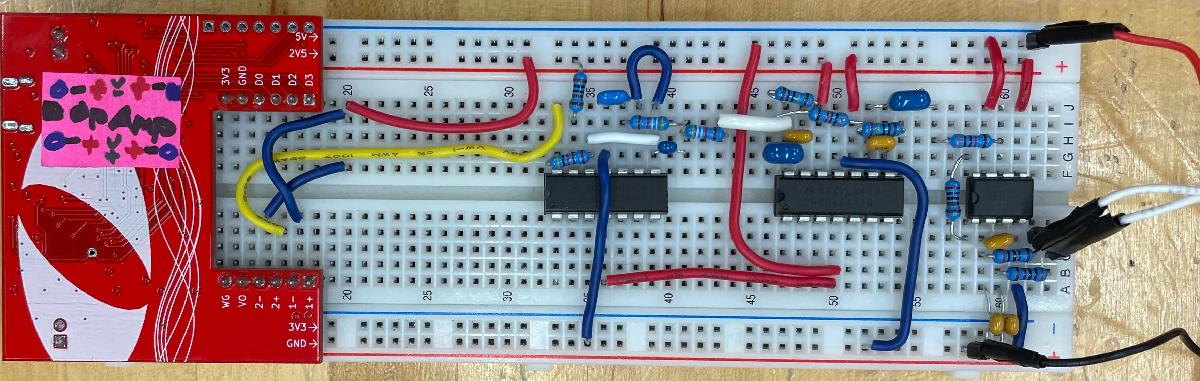

**Figure 1.** Our breadboard with our completed circuit. Leads running to the scale can be seen on the right-hand edge (two for power, two for signal).

## Results

### Bode Plots

We analyzed our filters by generating bode plots, as shown below:

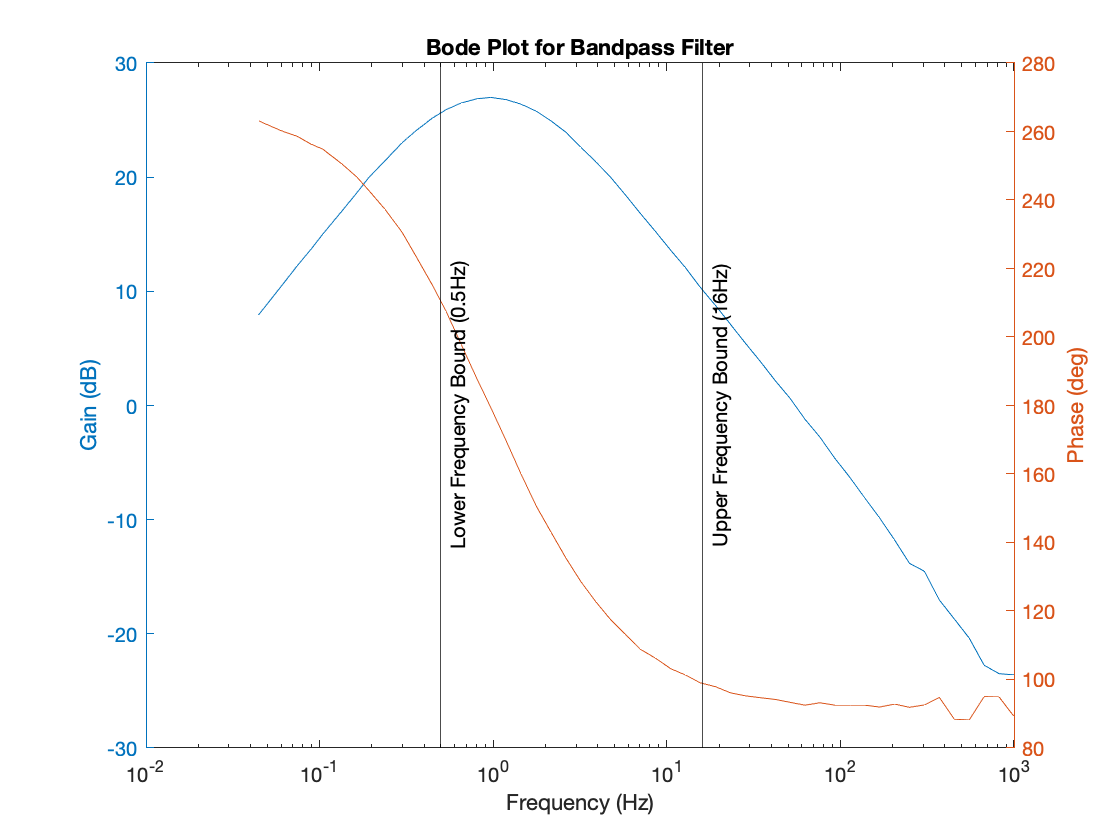

load("bode_bandpass.mat", "freq", "gain", "phase");
figure(2); clf;

yyaxis left;
semilogx(freq, gain);
ylabel("Gain (dB)");

yyaxis right;
semilogx(freq, phase);
ylabel("Phase (deg)");
xlabel("Frequency (Hz)");
xline(0.5, 'k', 'Lower Frequency Bound (0.5Hz)', ...
    "LabelVerticalAlignment", "middle");
xline(16, 'k', 'Upper Frequency Bound (16Hz)', ...
    "LabelVerticalAlignment", "middle");
title("Bode Plot for Bandpass Filter");

**Figure 2.** Bode plot of one bandpass filter (G = 33, f = 0.5Hz to 16Hz). This filter attenuates signals outside that range by a factor ten for each factor of ten that the frequency is outside of that range. Two are used in series for even stronger attenuation.

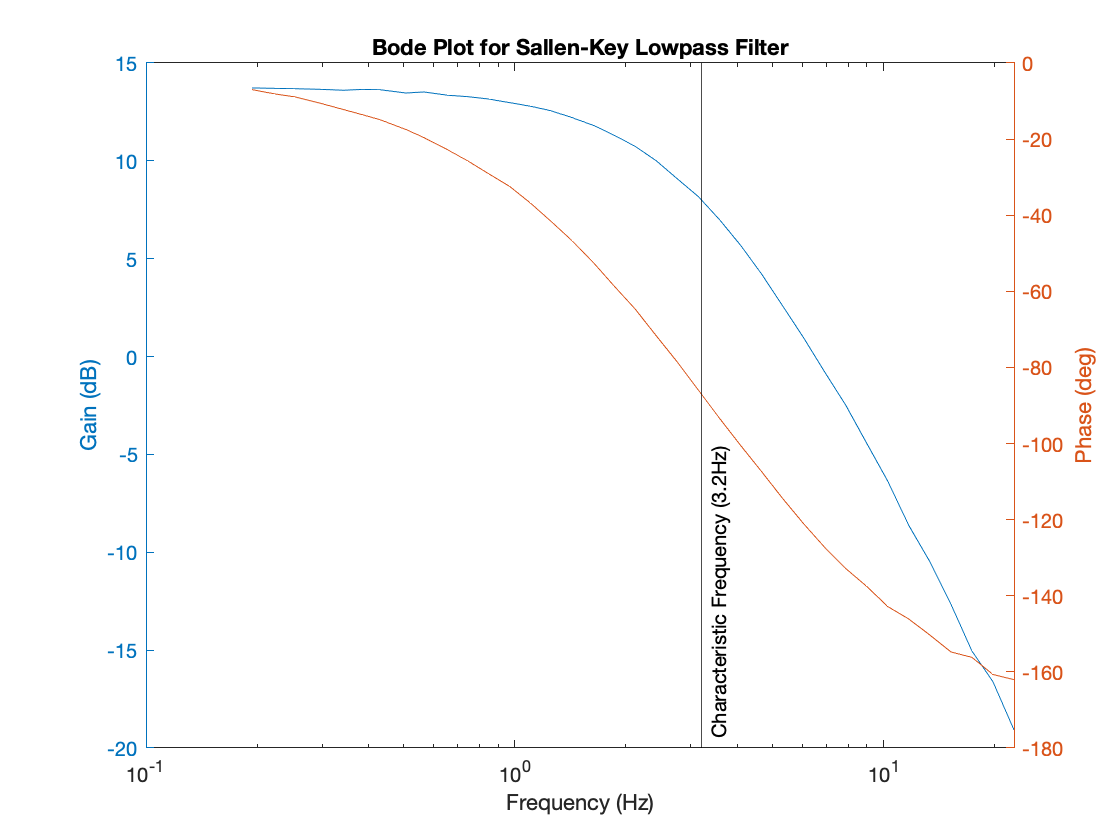

load("bode_lowpass.mat", "freq", "gain", "phase");
figure(3); clf;

yyaxis left;
semilogx(freq, gain);
ylabel("Gain (dB)");

yyaxis right;
semilogx(freq, phase);
ylabel("Phase (deg)");
xlabel("Frequency (Hz)");
xline(3.2, 'k', 'Characteristic Frequency (3.2Hz)', ...
    "LabelVerticalAlignment", "bottom");
title("Bode Plot for Sallen-Key Lowpass Filter");

**Figure 3.** Bode plot of our Sallen-Key lowpass filter (f = 3.2Hz). This filter attenuates signals outside that range by a factor ten for each factor of ten that the frequency is above that frequency.

### Measurement Results

Finally, we used our circuit to accomplish our goal of measuring the test subject's heartbeat. This was successful, as the subject's clean heartbeat can be seen in the graph of fully processed output voltage below:

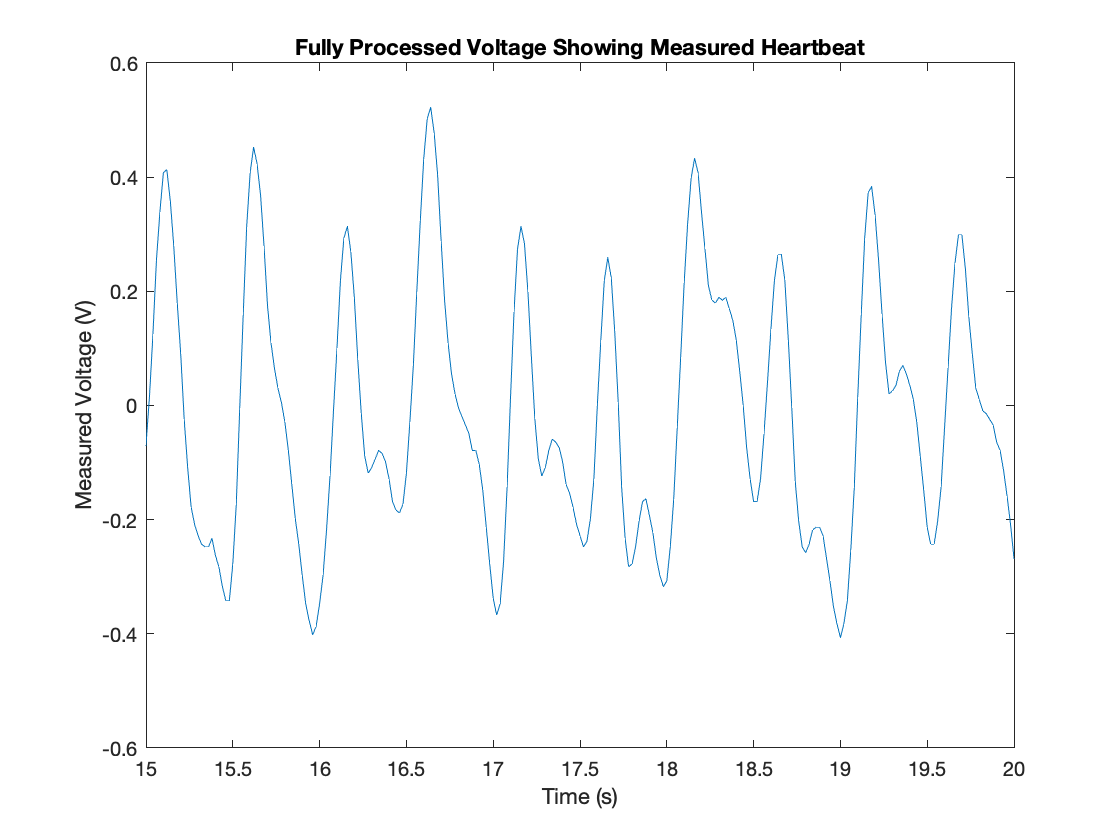

load("data.mat", "T", "V");

figure(4); clf;

plot(T, V);

title("Fully Processed Voltage Showing Measured Heartbeat");
xlabel("Time (s)");
ylabel("Measured Voltage (V)");

% The full dataset is too dense to make anything of
xlim([15, 20]);

**Figure 4.** Fully processed output voltage over time, showing the successful detection of the test subject's heartbeat.

## Finishing Remarks

In this experiment, we demonstrated the viability of detecting a human's heartbeat by measuring the downwards force exerted on the ground (or, in this case, a digital scale) by their heart pushing blood upwards: a ballistocardiograph (BCG). We also demonstrated the viability of using the filtering and amplification techniques descirbed above to process the scale's signal such that the minute force from the heart can be detected.

However, using a BCG to measure heartrate is not without flaws. Most notably, the test subject must remain *extremely* still lest the force of their movements overwhelm the force of their heart. This is quite difficult to do, and makes it nearly impossible to detect any more than a few heartbeats. Given the miriad other, more robost, mechanisms available for measuring heart rate, the practicality of a BCG needs further evaluation.